# Car Motion Control to Avoid Obstacles with Fuzzy Logic Controller

## Problem Description

We are given a 2D space consisting of a car (dimensionless) and an obstacle (Fig. 1). Given an initial position of the car, and the position of the obstacle, our task is to control the car and 'drive' it towards the given coordinates in that 2D space avoiding collision.

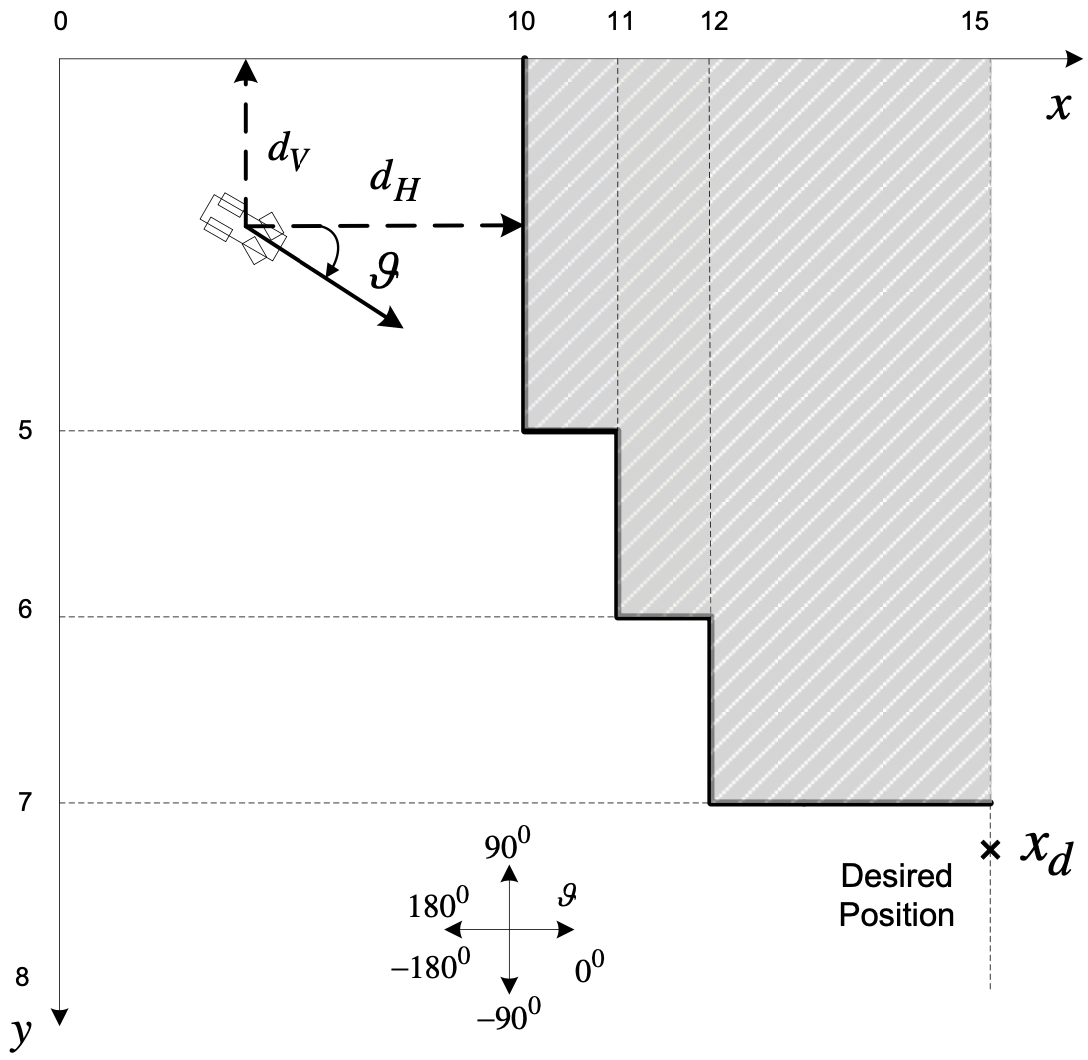

Fig. 1 Initial 2D space

The car 'has' sensors that constantly calculate the vertical $d_V$ and the horizontal $d_H$ distance from the obstacle. We are given that the car's speed is constant at $u=0\ldotp 05\;\frac{m}{s}$ and that the initial direction of the car is also given $[0\degree, 45\degree, 90\degree]
$. The car's starting point is: $\left(x_{\textrm{init}} ,y_{\textrm{init}} \right)=\left(9,4\ldotp 4\right)$ and the goal is to move it towards the $\left(x_d ,y_d \right)=\left(15,7\ldotp 2\right)$. It's important that the car arrives at the given $x_d$ and as close as possible to $y_d$.

We are asked to design an FLC that, knowing the $d_V$ and $d_H$ distance from the obstacle as well as the initial direction $\theta$ of the car, decides the alteration of the angle $d\theta$ in order to get the car to the given end coordinates $\left(x_d ,y_d \right)$.

So we must design the FLC having as inputs the distances and given initial angle, and as output the alteration of the angle according to the set below (Fig. 2).

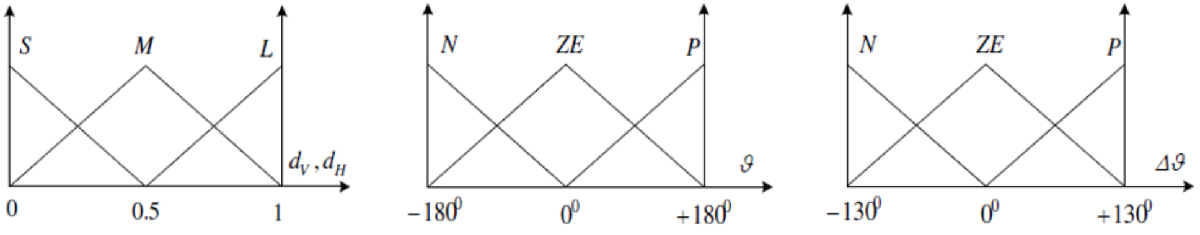

Fig. 2 Fuzzy variables

The rulebase must be designed based on rules like: 

Fig. 3 Rulebase sentence

## Fuzzy Logic Controller

The FLC was created based on the instructions in the script *rulebase.m*

clc; clearvars; close all;
addpath("lib")


% Uncomment below to create again the fis and the rulebase according to instructions
% run rulebase.m
FLC = readfis('FLC') 

FLC =   mamfis with properties:

                       Name: "FLC"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×27 fisrule]

	See 'getTunableSettings' method for parameter optimization.


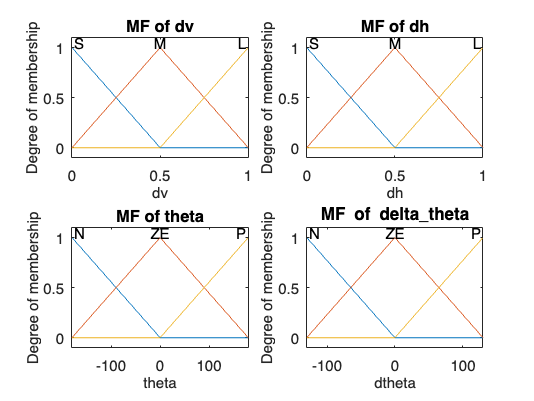

% % Plot membership functions.
figure;
subplot(2,2,1)
plotmf(FLC, 'input', 1);
title('MF of dv');

subplot(2,2,2)
plotmf(FLC, 'input', 2);
title('MF of dh');

subplot(2,2,3)
plotmf(FLC, 'input', 3);
title('MF of theta');

subplot(2,2,4)
plotmf(FLC, 'output', 1);
title('MF of delta\_theta');

## Creating 2D space

In order to test the car's ability to perform the given task, we must first initialize the environment.

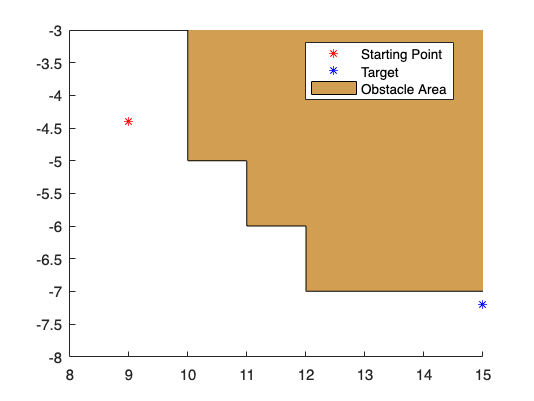

warning('off','all')

% Obstacle's position
obstacle = [10 0 ; 10 -5 ;11 -5 ; 11 -6 ; 12 -6 ; 12 -7 ; 15 -7];

% Car's position intialization
x_init = 9;
y_init = -4.4;
u = 0.05; % Speed
thetas = [0 45 90]; % The three variations of the car's starting direction

% Target coordinates
x_desired = 15;
y_desired = -7.2;
threshold = 0.15; % Allowed deviation/error from y_desired

figure();
hold on;
axis([8 15 -8 -3]);
plot(x_init, y_init, "r*", 'DisplayName', 'Starting Point');
plot(x_desired, y_desired, "b*", 'DisplayName', 'Target');
a = area(obstacle(:,1),obstacle(:,2), 'DisplayName','Obstacle Area');
set(a, 'FaceColor', '#D19E52');
legend('Location', 'Best');

We must now create the the functions that will drive the car. Thus we will need a way to measure the distance of the car from the obstacle at any given time, and another for driving and 'maneuvering' it, utilizing the FLC to turn the car. In the *liib/calc_distance.m* we have created a function which given the current coordinates, caluclates the distance from the obstacle.

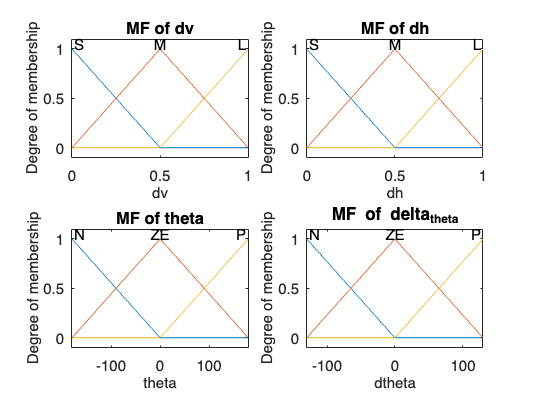

%% Plot membership functions.
figure;
subplot(2,2,1)
plotmf(FLC, 'input', 1);
title('MF of dv');

subplot(2,2,2)
plotmf(FLC, 'input', 2);
title('MF of dh');

subplot(2,2,3)
plotmf(FLC, 'input', 3);
title('MF of theta');

subplot(2,2,4)
plotmf(FLC, 'output', 1);
title('MF of delta_theta');

% Αρχικές τιμές εισόδων
x_init = 9;
y_init = 4.2;
theta_init = 0;   

% Επιθυμητή θέση
x_d = 15;
y_d = -7.2;

% Υπολογίζω την τροχιά του οχήματος για θ=0
theta_init = 0;
[x1 y1] = car_trojectory(x_init,y_init,theta_init,FLC);

message = "Η επανάληψη δεν ολοκληρώθηκε ποτέ"

figure
plot(boundary_x,boundary_y)

Unrecognized function or variable 'boundary_x'.

hold on
xlabel('x')
ylabel('y')
plot(x1,y1)
hold on
plot(x_d,y_d,'r*')
title('θ=0^o')

function[dis] = vertical_distance(x,y)
% Υπολογίζουμε την κάθετη απόσταση dV του οχήματος από το εμπόδιο
if (x>-5)
    dis = y;
elseif (x<= -5 && x> -6)
    dis = y +1 ;                % Αφαιρώ "1" από το y γιατί το εμπόδιο φτάνει μέχρι το boundary = 1
elseif (x<=-6 && y>-7)
    dis = y + 2;                % Αφαιρώ "2" από το y γιατί το εμπόδιο φτάνει μέχρι το boundary = 2
else 
    dis = y + 3;                % Αφαιρώ "3" από το y γιατί το εμπόδιο φτάνει μέχρι το boundary = 3
end
end

%%%%%%%%%%%%%%%%%%%%
function[dis] = horizontal_distance(x,y)
% Υπολογίζουμε την οριζόντια απόσταση dΗ του οχήματος από το εμπόδιο
if (y<1)
    dis = 10 - x;                % Αφαιρώ το x από το "5" γιατί το εμπόδιο φτάνει μέχρι το boundary = 5
elseif (y>=1 && y<2)
    dis = 11 - x;                % Αφαιρώ το x από το "6" γιατί το εμπόδιο φτάνει μέχρι το boundary = 6
elseif (y>=2 && y<3)
    dis = 12 - x;                % Αφαιρώ το x από το "7" γιατί το εμπόδιο φτάνει μέχρι το boundary = 7
else
    dis = inf;                  % Δεν υπάρχει εμπόδιο για y>=3
end
end





function[x y] = car_trojectory(x0,y0,theta0,FLC)

% (x,y) η τελική θέση του οχήματος
x = x0;
y = y0;
theta = theta0;

% Ταχύτητα οχήματος
v = 0.05;                   % 0.05 m/sec

% Υπολογίζω την τροχιά του οχήματος
flag = 1;                   % "1" = το όχημα ΔΕΝ έφτασε στην επιθυμητή θέση, "0" = το όχημα έφτασε στην επιθυμητή θέση
i = 1;
while (flag)
    % Υπολογίζω τις αποστάσεις dV (κάθετη) και dH (οριζόντια) από το εμπόδιο
    dV = vertical_distance(x(i),y(i));
    dH = horizontal_distance(x(i),y(i));

    % Κανονικοποιούμε στο διάστημα [0,1]
    dV = min(dV,1);
    dV = max(dV,0);
    dH = min(dH,1);
    dH = max(dH,0);

    % Υπολογίζουμε τη μεταβολή της γωνίας dθ με την βοήθεια της Βάσης
    % Κανόνων του Fuzzy συστήματος
    dtheta = evalfis(FLC,[dV dH theta]);
    % Προσθέτω τη μεταβολή της γωνίας για να βρω την νέα γωνία (κατεύθυνση)
    % του οχήματος
    theta = theta + dtheta;
    % Η γωνία θ έχει πεδίο ορισμού το [-180,180]
    if (theta>180)
        theta = theta - 360;
    elseif (theta<-180)
        theta = theta + 360;
    end

    % Υπολογίζουμε τη νέα θέση (x,y) του οχήματος
    i = i + 1;
    x(i) = x(i-1) + v*cosd(theta);              % Θεωρώ dt=1 sec
    y(i) = y(i-1) + v*sind(theta);
    
    % Ελέγχουμε αν το όχημα έφτασε στην επιθυμητή θέση
    flag = check(x(i),y(i),i);
end
end

function[flag] = check(x,y,i)
% flag:     "1" =   το όχημα ΔΕΝ έφτασε ακόμη στην επιθυμητή θέση, 
%           "0" =   το όχημα έφτασε στην επιθυμητή θέση 
%                   ή τράκαρε στο εμπόδιο
%                   ή έκανε πολλές επαναλήψεις και δεν έφτασε ποτέ
flag = 1;
if (y<0 && y>-5)
    if (x>10)
        flag = 0;
    end
elseif (y<=-5 && y>-6)
    if (x>11)
        flag = 0;
    end
elseif (y<=-6 && y>-7)
    if (x>12)
        flag =0;
    end
elseif (y<-7)
    if (x>15)
        flag = 0;
    end
end

if (i>10^6)
    flag = 0;
    message = "Η επανάληψη δεν ολοκληρώθηκε ποτέ"
end
end